### Load

clear; clc; close all;
%noisySignal = load('lab5files\data\X.dat');
noisySignal = load('data\Emma\EMG\Emma_EMG_FullFlex_Leads.csv');
cleanSignal = load('data\Emma\EMG\Emma_EMG_Relaxed_Leads.csv');

fs = 512; % Sampling rate 256 512
N=length(noisySignal); 
t=0:1/fs:(N-1)/fs; % time line for plotting

% Plot the original signals
multiPlot(t, noisySignal, 'Noisy original signal', 't', 'mV')
%multiPlot(t, cleanSignal, 'Clean original signal', 't', 'mV')

### Preprocess

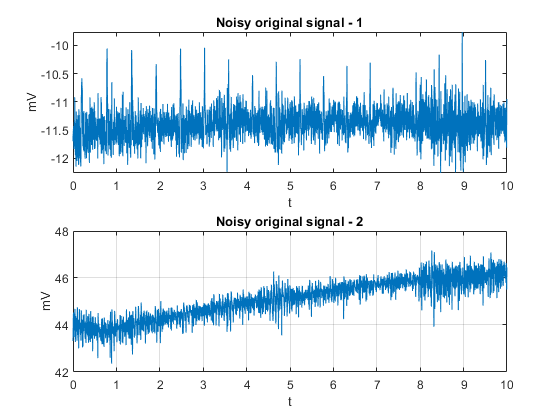

noisySignal = preprocess(noisySignal, fs, t);

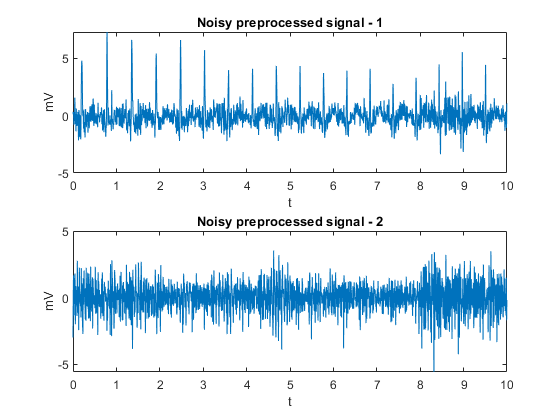

%cleanSignal = preprocess(cleanSignal, fs, t);

noisySignal = whitenRows(noisySignal')';
cleanSignal = whitenRows(cleanSignal')';

% Plot the preprocessed signals
multiPlot(t, noisySignal, 'Noisy preprocessed signal', 't', 'mV')

%multiPlot(t, cleanSignal, 'Clean preprocessed signal', 't', 'mV')

### ICA test

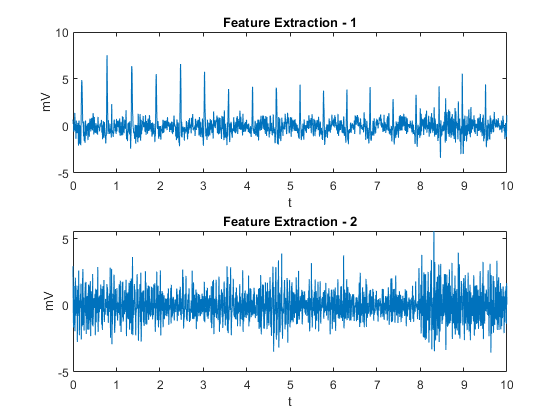

q = 2; % Amount of features to be extracted
model = rica(noisySignal, q);
features = transform(model, noisySignal);

multiPlot(t, features, 'Feature Extraction', 't', 'mV')


kur = kurtosis(features)

kur =    12.9108    4.0055



[~, I] = sort(kur, 'descend');



### Fast ICA test

zica = fastICA(noisySignal', 2, 'negentropy');

***** Fast ICA (negentropy) *****
Iter 001: max(1 - |<w001, w000>|) = 0.2006
Iter 002: max(1 - |<w002, w001>|) = 0.007024
Iter 003: max(1 - |<w003, w002>|) = 0.0008978
Iter 004: max(1 - |<w004, w003>|) = 7.89e-06
Iter 005: max(1 - |<w005, w004>|) = 3.872e-08



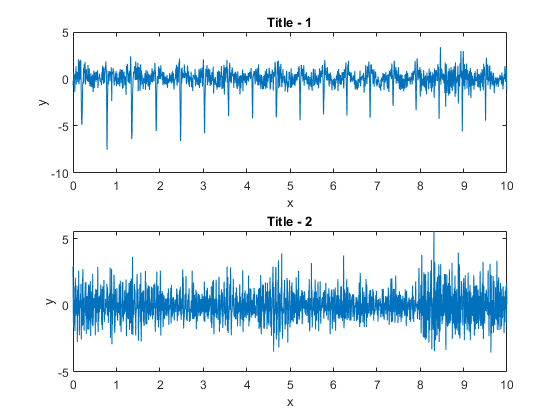


multiPlot(t, zica')

### SVD test

[U, S, V] = svd(noisySignal);
Srec = S

Srec =    71.5472         0
         0   71.5472
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


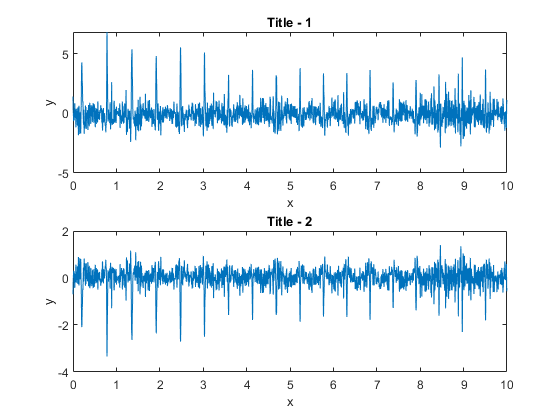

Srec(1,1) = 0;
%Srec(3,3) = 0;
%Srec(I(1:end-1),I(1:end-1)) = 0

Yrec = U*Srec*V';
figure
multiPlot(t,Yrec)

% figure
% plot(Yrec(:,2))

### Frequency Spectrum

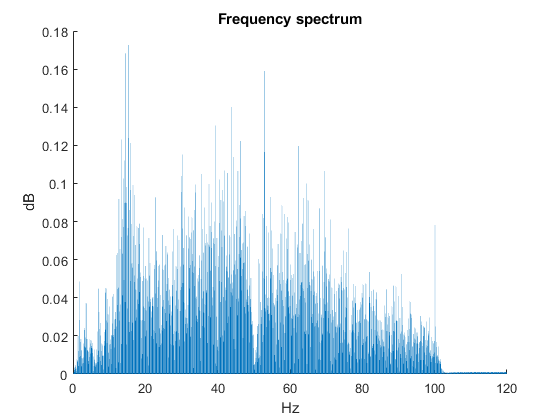

X = fft(noisySignal(:,2));
p2 = abs(X)/N;
p1 = p2(1:N/2+1);
p1(2:end-1) = 2*p1(2:end-1);
f = fs*(0:(N/2))/N; %linspace(0,fs/2, L/2+1)

%unfiltered freq
figure
%subplot(2,1,1); 
hold on;
bar(f, p1);
title('Frequency spectrum')
xlabel('Hz')
ylabel('dB')
%ylim([0 0.08])
xlim([0 120])